# MPSA_regression_transformedResponse

Multiple regressions of MPS and MPB using transformed values (log transformed or z-score)

clear, clc, close all

% Update to the folder in which the manuscript code was saved
manuscript_codePath = '/Users/taylormccoll/Documents/SFU/1. Ph.D./1. Research Projects/2. MPSA and analyses/4. Writing/2. Manuscript/ManuscriptCodeSharing/MultifactorialCauseOfAnabolicResistance/';

% addpath to MPS kinetic model code
FolderPath_model = fileparts(fullfile(manuscript_codePath, 'McColl_2023_Muscle Protein Synthesis Kinetic Model_230919/'));
addpath(genpath(FolderPath_model)) % add all subfolders within 'FolderPath'

% addpath to MPSA folder
FolderPath_mpsa = fileparts(fullfile(manuscript_codePath, '1. KineticModelMPSA/'));
addpath(genpath(FolderPath_mpsa))

## File Output

Creates an 'Output Plots' folder with a subplot of the current date and time.

FilePath = fullfile(FolderPath_mpsa, 'Output Plots/');
NewFolder = datestr(now, 'yy-mm-dd HH-MM-SS');
    CumulativeOutput = mkdir(FilePath, NewFolder);
FilePathCumulative = fullfile(FilePath, NewFolder);

## Model Inputs

GlucoseInfRate = 75e-3 *(1/180.16); % 75 mg/min glucose infusion; converted to units of moles/min
LeucineInfRate = 2.5e-3*(1/131.17); % 25 mg/min leucine infusion; converted to units of moles/min

% Subject specific data (used to calculate compartment volumes)
gender = 1; % 1=male, 0=female
height = 173; % cm
mass = 72.1; % kg
age = 41.9; % years
bia = 517; % Bioelectical Impedance (Ohms)
subjectData = [gender, height, mass, age, bia];

% Initial Conditions
x0 = xlsread('230922_Initial Values, IOM', '3. Oscillatory insulin'); % reduced phospho-proteins
x0 = x0(:,1);

% K-Values
KValueVector_given = xlsread('230922_K-values, IOM', '230930');

%Experimental Data
ExpData = '230221_experimental data.xlsx';

% Equilibrium and run durations
EquilibriumDuration = 300;
RunDuration = 200;

## Import the plausible MPSA parameter values

% MPS
MPS_plausible_file = "Plausible_MpsOutput_24-09-15 16-49-15.csv";
dataName_full = fullfile(FolderPath_mpsa,'/mpsaData/240915_k6_10_reduced', MPS_plausible_file);
MPS_plausible_read = csvread(dataName_full); MPS_plausible = MPS_plausible_read';

% MPB
MPB_plausible_file = "Plausible_MpbOutput_24-09-15 16-49-15.csv";
dataName_full = fullfile(FolderPath_mpsa,'/mpsaData/240915_k6_10_reduced', MPB_plausible_file);
MPB_plausible_read = csvread(dataName_full); MPB_plausible = MPB_plausible_read';

% NB
NB_plausible_file = "Plausible_NbOutput_24-09-15 16-49-15.csv";
dataName_full = fullfile(FolderPath_mpsa,'/mpsaData/240915_k6_10_reduced', NB_plausible_file);
NB_plausible_read = csvread(dataName_full); NB_plausible = NB_plausible_read';

% kValues
kValues_plausible_file = "Plausible_kValues_24-09-07 11-45-23.csv";
dataName_full = fullfile(FolderPath_mpsa,'/mpsaData/240915_k6_10_reduced', kValues_plausible_file);
kValues_plausible_read = csvread(dataName_full); kValues_plausible = kValues_plausible_read;

% Concentrations
concentrations_plausible_file = "Plausible_concentrations_24-09-07 11-45-23.csv";
dataName_full = fullfile(FolderPath_mpsa,'/mpsaData/240915_k6_10_reduced', concentrations_plausible_file);
concentrations_plausible_read = csvread(dataName_full); concentrations_plausible = concentrations_plausible_read;


## Reducing k-values and concentrations to those parameters that change

Re-writing to table with labels

% k-values
kValues_data_change = kValues_plausible';
kValues_data_change(:,[1:5,8,48:50,68]) = []; % removed k5 -> not used 
kValues_data_table = array2table(kValues_data_change);
kValue_labels = strcat('k',string([6:7,9:47,51:67,69])); % removed k5 -> not used
kValues_data_table.Properties.VariableNames = kValue_labels;

% Concentrations
concentrations_data_change = concentrations_plausible';
concentrations_data_change(:,[1:2,33:40]) = []; % removing all concentrations that start at zero
concentration_data_table = array2table(concentrations_data_change);
concentrationLabels = {'Ins_Plasma', 'Leu_Plasma', 'kic_Plasma', 'Leu_Intrac', 'kic_Intrac', 'Protein', ...
    'IR_beta', 'p_IR_beta_Y1164', 'p_IR_beta_refr', 'IRS1', 'p_IRS1_Y', 'p_IRS1_S', 'PI3K', ...
    'p_IRS1_Y_PI3K_clx', 'PDK1', 'p_PDK1', 'Akt', 'p_Akt_T308', 'p_Akt_S473', 'p_Akt_T308_S473', ...
    'TSC_clx', 'p_TSC_clx', 'mTORC1_inactive', 'mTORC1_active', 'p70S6K1', 'p_p70S6K1_T389', ...
    'PI3K_var', 'p_PI3K_var', 'mTORC2', 'p_mTORC2_S2481'}; %, 'Insulin_{int}', 'Glucose_{pl}', 'x1', 'x2', 'x3'};
concentration_data_table.Properties.VariableNames = concentrationLabels;

% Combining parameters
allParameters = [kValues_data_table, concentration_data_table];

## Parameter values: keep as raw values or transform to log or z-score

% raw values or transform to log10 values or z-scores
% allParameters_log = allParameters{:,1:89}; % Raw values
allParameters_log = log10(allParameters{:,1:89}); % log transform
% allParameters_log = zscore(allParameters{:,1:89}); % z-score transform

% converting parameters into a table format with names
% including MPS, MPB, and NB in the same table for use with the "formula" (allows for
% parameter names in regression output)
parameter_table = array2table(allParameters_log, 'VariableNames', [kValue_labels, concentrationLabels]);

data_table = [parameter_table, table(MPS_plausible, 'VariableNames', {'MPS'}), ...
    table(MPB_plausible, 'VariableNames', {'MPB'})];

data_table.MPS_transform = log10(data_table.MPS);
data_table.MPB_transform = log10(data_table.MPB);

## 1a) MPS: Regression

Main effects only

formula = strcat({'MPS_transform ~ '}, strjoin([kValue_labels, concentrationLabels], ' + '));
mdl_MPS_mainEffect = fitlm(data_table, formula);

Regression details

% Display top n coefficients
nCoeff = 20;
coefficients = mdl_MPS_mainEffect.Coefficients;
sorted_coeff_mainEffect_MPS = sortrows(coefficients(2:end,:), 'pValue'); % removed intercept from the sorted values
top_n_coeff_MPS = sorted_coeff_mainEffect_MPS(1:nCoeff, :);
 
R_square = mdl_MPS_mainEffect.Rsquared.Adjusted;
aic = mdl_MPS_mainEffect.ModelCriterion.AIC;

disp(['MP Synthesis: Regression with main effect terms only'])

MP Synthesis: Regression with main effect terms only


disp(['Top ', num2str(nCoeff), ' coefficients: '])

Top 20 coefficients: 


disp(top_n_coeff_MPS)

                       Estimate        SE         tStat       pValue   
                       _________    _________    _______    ___________

    k10                 -0.74969     0.006098    -122.94              0
    k11                  0.17224    0.0033726     51.071              0
    k14                  -0.1595     0.003356    -47.525              0
    k15                  0.81091     0.004111     197.25              0
    k39                  0.35608    0.0033919     104.98              0
    k40                  0.39896    0.0034479     115.71              0
    k42                 -0.39655    0.0034493    -114.97              0
    k43                 -0.29239    0.0033071    -88.412              0
    

disp(['R squared, adj: ', num2str(R_square)])

R squared, adj: 0.95719


disp(['AIC: ', num2str(aic)])

AIC: -11528.0428


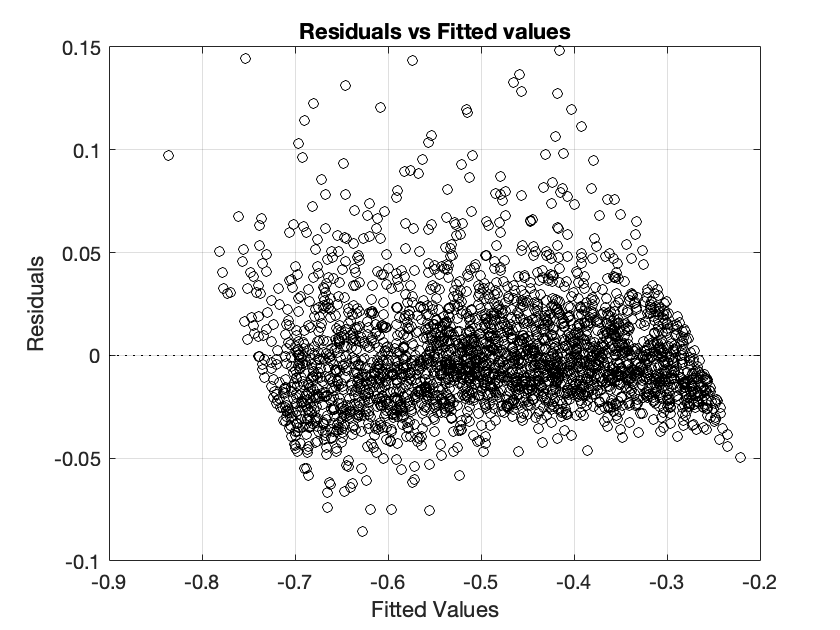

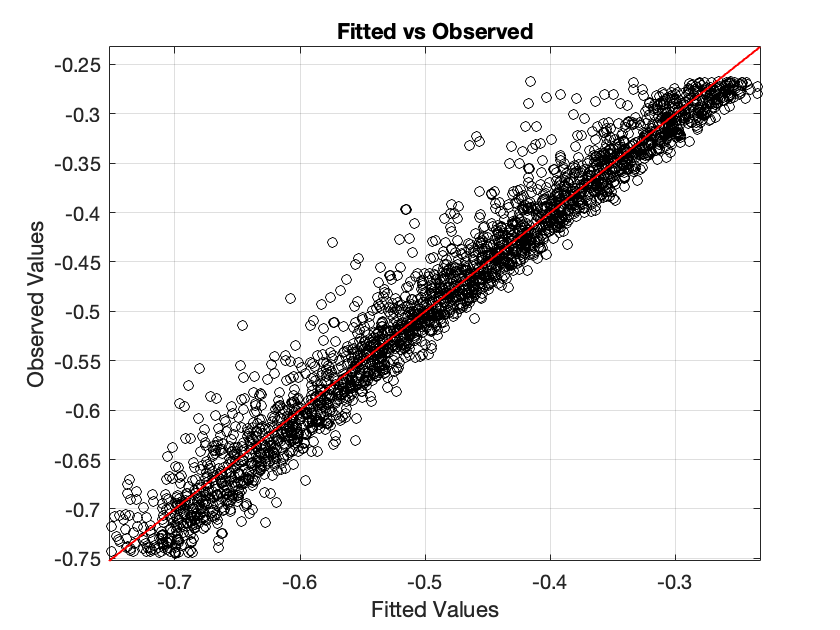

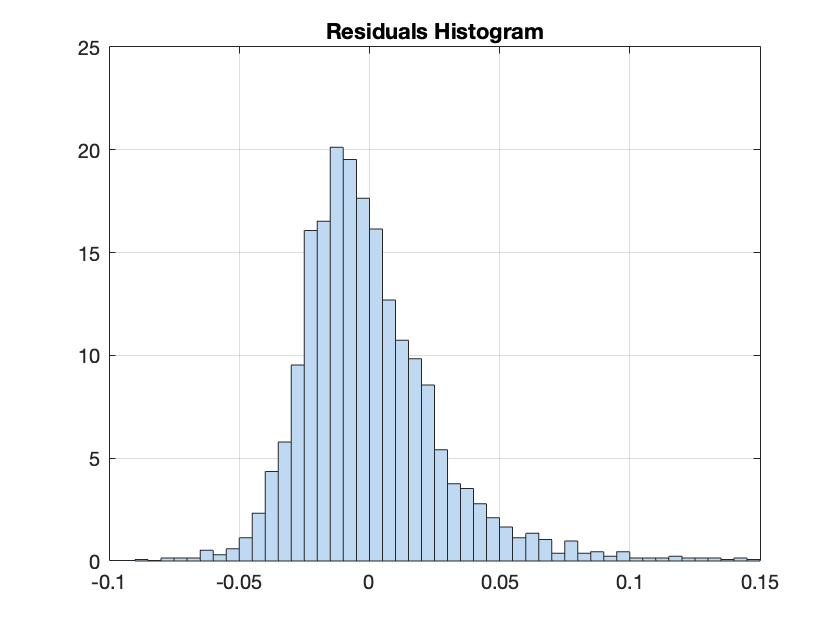

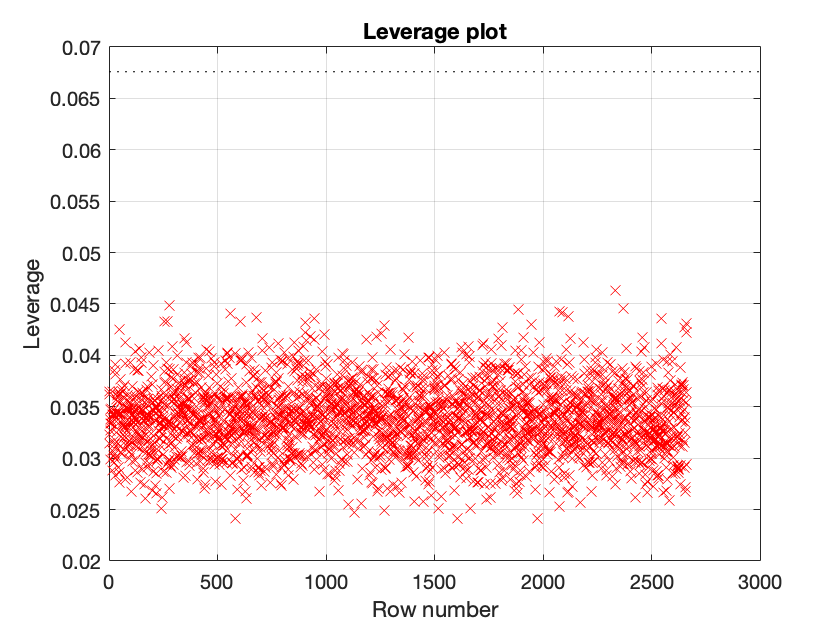

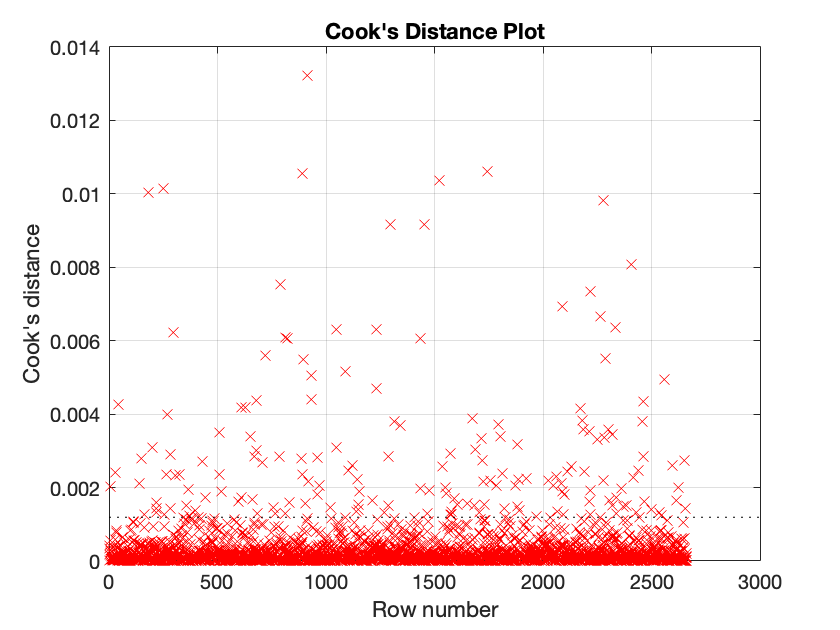

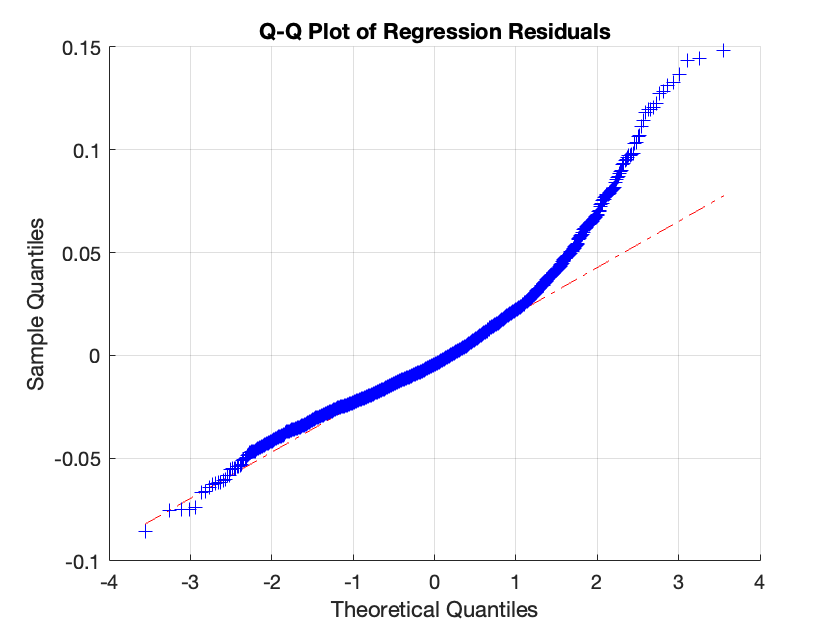


% Diagnostic plots
modelName = 'MPS, main effects';
regressionDiagnostics_MpsTransformed(mdl_MPS_mainEffect, modelName, FilePathCumulative);

## 1b) MPS: Regression

Interaction terms included

MP Synthesis: Regression with interactions of top 35 terms


Total number of model parameters: 685


R squared, adj: 0.9866


AIC: -14131.2321


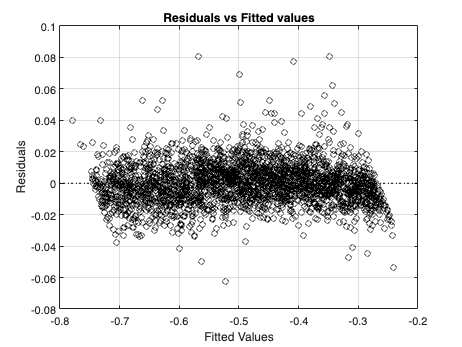

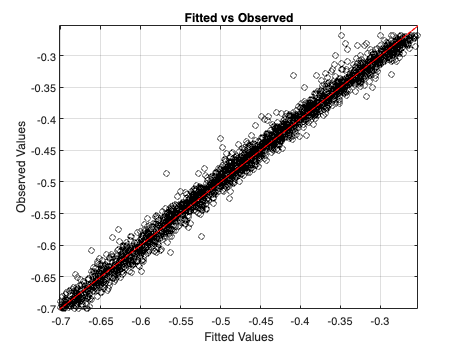

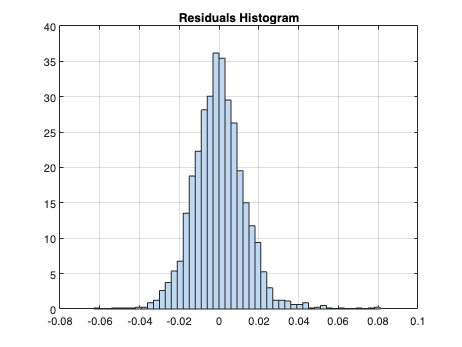

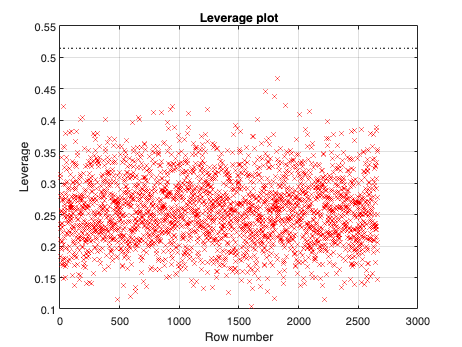

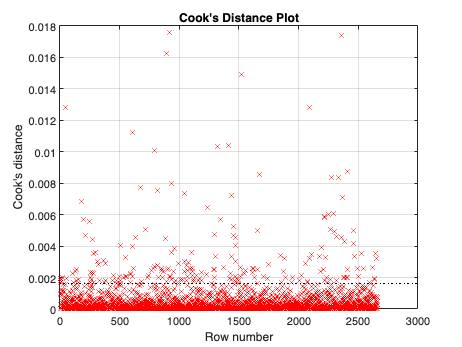

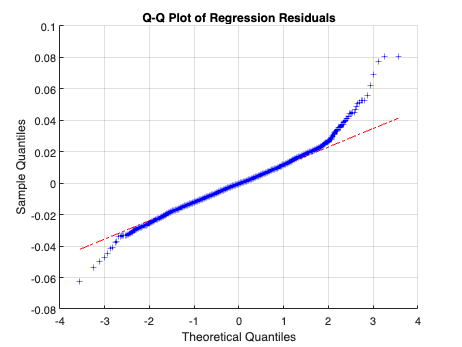

% Select to loop through increasing numbers of interaction terms or a set
% number of interaction terms
% nParamInteract_for = [5, 10, 15, 20, 25, 30, 35, 40, 45]; % loop through increasing interaction terms
nParamInteract_for = 35; % set number of interaction terms

for j = 1:length(nParamInteract_for)
    % Create interaction terms for the top n parameters
    top_params = sorted_coeff_mainEffect_MPS(1:nParamInteract_for(j),:);
    top_params = top_params.Row;
    
    % Create interaction terms 
    interactionTerms = nchoosek(top_params, 2);
    
    % Add interaction terms to the regression formula
    interaction_str = cell(size(interactionTerms, 1),1);
    for i = 1:size(interactionTerms, 1)
        interaction_str{i} = [interactionTerms{i,1}, '*', interactionTerms{i,2}];
    end
    
    % Join the interaction terms into a single string
    interaction_str = strjoin(interaction_str, ' + ');
    
    % combined regression formula (main effects and interaction terms)
    formulaInteractions = strcat(formula, ' + ', interaction_str);
    
    % run regression with interaction terms
    mdl_MPS_interaction = fitlm(data_table, formulaInteractions);

    % Regression details
    
    % Display top n coefficients
    nCoeff = 20;
    coefficients = mdl_MPS_interaction.Coefficients;
    sorted_coeff = sortrows(coefficients(2:end,:), 'pValue'); % removed intercept from the sorted values
    top_n_coeff_int_MPS = sorted_coeff(1:nCoeff, :);
    
    R_square = mdl_MPS_interaction.Rsquared.Adjusted;
    aic_MPS = mdl_MPS_interaction.ModelCriterion.AIC;
    
    disp(['MP Synthesis: Regression with interactions of top ', num2str(nParamInteract_for(j)), ' terms'])
    disp(['Total number of model parameters: ', num2str(size(interactionTerms,1) + size(allParameters,2) +1)]) % +1 for the intercept
%     disp(['Top ', num2str(nCoeff), ' coefficients: '])
%     disp(top_n_coeff_int_MPS)
    disp(['R squared, adj: ', num2str(R_square)])
    disp(['AIC: ', num2str(aic_MPS)])

    % Diagnostic plots
    modelName = sprintf('MPS, main effects + top %d interactions', nParamInteract_for(j));
    regressionDiagnostics_MpsTransformed(mdl_MPS_interaction, modelName, FilePathCumulative);

end


disp(['Top ', num2str(nCoeff), ' coefficients: '])

Top 20 coefficients: 


disp(top_n_coeff_int_MPS)

                    Estimate       SE        tStat       pValue  
                    ________    ________    _______    __________

    k11:k14         -0.24688    0.013402    -18.421    4.6359e-70
    k28:Protein      0.13915    0.012443     11.183    3.3938e-28
    k26:PDK1        -0.13085    0.011851    -11.041    1.5214e-27
    k28:Akt         -0.13216    0.012305     -10.74    3.4149e-26
    k9:Protein       0.12943    0.012392     10.445    6.7952e-25
    k9:Akt          -0.12353    0.012348    -10.004    5.1011e-23
    Protein:PDK1    -0.12303    0.012307    -9.9975    5.4337e-23
    k9:k28           0.12328    0.012364     9.9708    7.0205e-23
    Protein:Akt     -0.12416    0.012545    -9.897


% % Diagnostic plots
% modelName = sprintf('MPS, main effects + top %d interactions', nParamInteract_for);
% regressionDiagnostics_MpsTransformed(mdl_MPS_interaction, modelName, FilePathCumulative);



## 1c) MPS Regression: p-1 parameters

2b needs to be run with only the number of interactions of the most predictive model. 

-> MPS: interactions of top 30 terms 

aic_MPS_optimal = aic_MPS;

allParameter_names = [kValue_labels, concentrationLabels];

% Pre-allocate arrays to store results
MPS_sa_R2_values = zeros(length(allParameter_names), 1);
MPS_sa_AIC_values = zeros(length(allParameter_names), 1);

% Loop over each parameter for p-1 sensitivity analysis
for i = 1:length(allParameter_names)
    % Retrieve parameter to remove
    param_to_remove = allParameter_names{i};

    % 1. Create the new formula by removing the main effect and any
    % interactions involving the parameter
    % Remove main effect
    remaining_main_effects = setdiff(allParameter_names, param_to_remove);

    % Locate and remove any interaction terms involving the removed
    % parameter
    remaining_interactions = {};
    for j = 1:length(top_params)
        for k = j+1:length(top_params)
            interaction = [top_params{j}, '*', top_params{k}];
            if ~contains(interaction, param_to_remove)
                remaining_interactions = [remaining_interactions; interaction]; % add comment*
            end
        end
    end

    % Construct new formula
    main_effect_str = strjoin(remaining_main_effects, ' + ');
    interactions_str = strjoin(remaining_interactions, ' + ');
    new_formula_sa = strcat({'MPS_transform ~ '}, main_effect_str); 
    if ~isempty(interaction_str)
        new_formula_sa = strcat(new_formula_sa, ' + ', interactions_str);
    end

    % 2. Fit the model
    mdl_MPS_sa = fitlm(data_table, new_formula_sa);

    % 3. Record the model criterion measures
    MPS_sa_R2_values(i) = mdl_MPS_sa.Rsquared.Adjusted;
    MPS_sa_AIC_values(i) = mdl_MPS_sa.ModelCriterion.AIC;

    % Progress
    fprintf('Iteration %d/%d: Removed %s\n', i, length(allParameter_names), param_to_remove);

end

Iteration 1/89: Removed k6
Iteration 2/89: Removed k7
Iteration 3/89: Removed k9
Iteration 4/89: Removed k10
Iteration 5/89: Removed k11
Iteration 6/89: Removed k12
Iteration 7/89: Removed k13
Iteration 8/89: Removed k14
Iteration 9/89: Removed k15
Iteration 10/89: Removed k16
Iteration 11/89: Removed k17
Iteration 12/89: Removed k18
Iteration 13/89: Removed k19
Iteration 14/89: Removed k20
Iteration 15/89: Removed k21
Iteration 16/89: Removed k22
Iteration 17/89: Removed k23
Iteration 18/89: Removed k24
Iteration 19/89: Removed k25
Iteration 20/89: Removed k26
Iteration 21/89: Removed k27
Iteration 22/89: Removed k28
Iteration 23/89: Removed k29
Iteration 24/89: Removed k30
Iteration 25/89: Removed k31
Iteration 26/89: Removed k32
Iteration 27/89: Removed k33
Iteration 28/89: Removed k34
Iteration 29/89: Removed k35
Iteration 30/89: Removed k36
Iteration 31/89: Removed k37
Iteration 32/89: Removed k38
Iteration 33/89: Removed k39
Iteration 34/89: Removed k40
Iteration 35/89: Removed k

% Tabulate results
MPS_sa_results = table(allParameter_names', MPS_sa_R2_values, MPS_sa_AIC_values, ...
    MPS_sa_AIC_values - repmat(aic_MPS_optimal, 89, 1), ...
    'VariableNames', {'Parameter Removed', 'Adjusted R2', 'AIC', 'Delta AIC'});

% Sort according to R2 values
MPS_sa_results_sortR2 = sortrows(MPS_sa_results, 'Adjusted R2', 'ascend');
MPS_sa_results_sortAic = sortrows(MPS_sa_results, 'Delta AIC', 'descend');

disp(MPS_sa_results_sortR2(1:20,:))

    Parameter Removed    Adjusted R2      AIC      Delta AIC
    _________________    ___________    _______    _________

    "k15"                  0.32724        -3726      10405  
    "p70S6K1"              0.66275      -5564.9     8566.3  
    "k10"                  0.71998      -6060.2       8071  
    "k40"                  0.75614      -6428.3     7702.9  
    "k42"                  0.76837      -6565.4     7565.9  
    "mTORC1_inactive"      0.78182      -6724.8     7406.5  
    "k39"                  0.79421      -6880.3     7250.9  
    "k43"                  0.84805        -7688     6443.2  
    "k11"                  0.93613      -9996.3     4134.9  
    "k14"                  0.94133       -10222     3908.8  
    "Protein"              0.96534       -11624     2507.4  
    "k9"                   0.97039       -12043     2087.8  
    "k28"

% Write table to file
MPS_tableName = 'MPS_p-1 sensitivity analysis.csv';
MPS_table_fullName = fullfile(FilePathCumulative, MPS_tableName);
writetable(MPS_sa_results_sortR2, MPS_table_fullName);

## 2a) MPB Regression

Main effect terms only

formula = strcat({'MPB_transform ~ '}, strjoin([kValue_labels, concentrationLabels], ' + '));
mdl_MPB_mainEffect = fitlm(data_table, formula);

Regression details

% Display top n coefficients
nCoeff = 10;
coefficients = mdl_MPB_mainEffect.Coefficients;
sorted_coeff_mainEffect_MPB = sortrows(coefficients(2:end,:), 'pValue'); % removed intercept from the sorted values
top_n_coeff_MPB = sorted_coeff_mainEffect_MPB(1:nCoeff, :);

R_square = mdl_MPB_mainEffect.Rsquared.Adjusted;
aic = mdl_MPB_mainEffect.ModelCriterion.AIC;

disp(['MP Breakdown: Regression with main effect terms only'])

MP Breakdown: Regression with main effect terms only


disp(['Top ', num2str(nCoeff), ' coefficients: '])

Top 10 coefficients: 


disp(top_n_coeff_MPB)

               Estimate       SE         tStat       pValue   
               ________    _________    _______    ___________

    k9          0.73662    0.0099509     74.025              0
    k25        -0.53177    0.0097212    -54.702              0
    k26         0.52181    0.0096807     53.902              0
    k27        -0.59403    0.0098261    -60.455              0
    k28         0.67511    0.0097278       69.4              0
    Protein     0.92908    0.0099585     93.296              0
    PDK1       -0.63843    0.0097485     -65.49              0
    Akt        -0.72788    0.0099499    -73.154              0
    IRS1       -0.42457    0.0095923    -44.262    1.2053e-318
    PI3K 

disp(['R squared, adj: ', num2str(R_square)])

R squared, adj: 0.94835


disp(['AIC: ', num2str(aic)])

AIC: -5530.3716


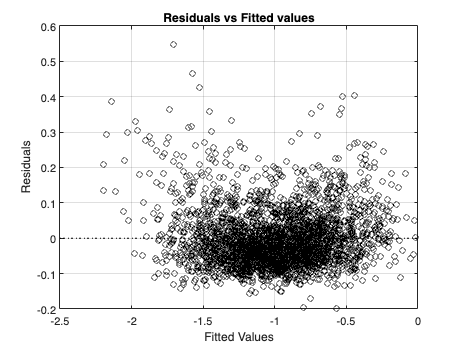

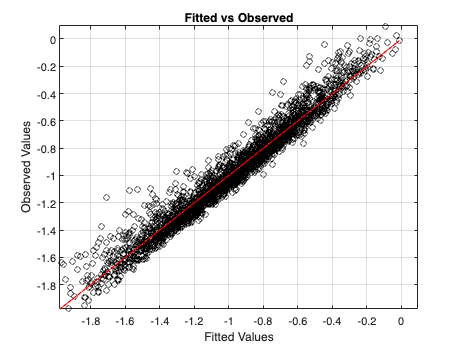


% Diagnostic plots
modelName = 'MPB, main effects only';
regressionDiagnostics_MpbTransformed(mdl_MPB_mainEffect, modelName, FilePathCumulative);

## 2b) MPB Regression

Interaction terms included

MP Breakdown: Regression with interactions of top 45 terms


Total number of model parameters: 1080


R squared, adj: 0.99093


AIC: -9476.7199


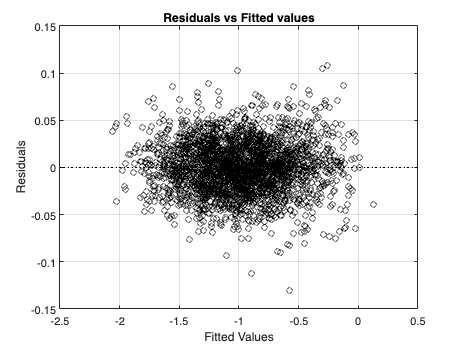

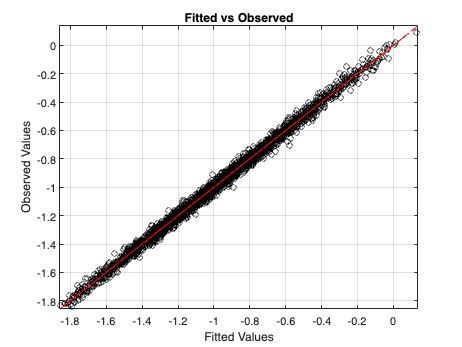

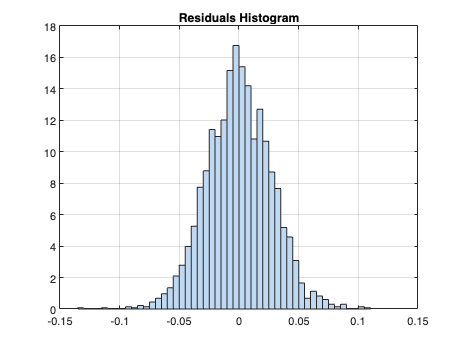

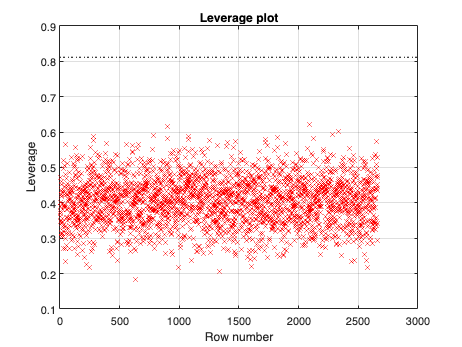

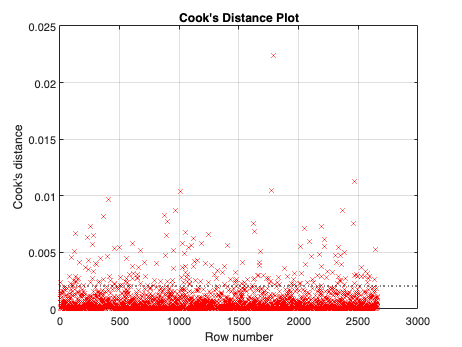

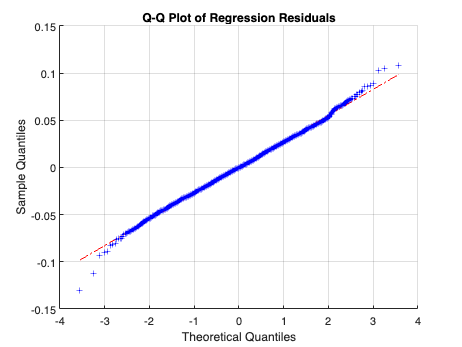

% Select to loop through increasing numbers of interaction terms or a set
% number of interaction terms
% nParamInteract_for = [5, 10, 15, 20, 25, 30, 35, 40, 45]; % loop through increasing interaction terms
nParamInteract_for = 45; % set number of interaction terms

for j = 1:length(nParamInteract_for)
    % Create interaction terms for the top n parameters
    top_params = sorted_coeff_mainEffect_MPB(1:nParamInteract_for(j),:);
    top_params = top_params.Row;
    
    % Create interaction terms 
    interactionTerms = nchoosek(top_params, 2);
    
    % Add interaction terms to the regression formula
    % interaction_str = '';
    interaction_str = cell(size(interactionTerms, 1),1);
    for i = 1:size(interactionTerms, 1)
    %     interaction_str = [interaction_str, ' + ', interactionTerms{i,1}, '*', interactionTerms{i,2}];
        interaction_str{i} = [interactionTerms{i,1}, '*', interactionTerms{i,2}];
    end
    
    % Join the interaction terms into a single string
    interaction_str = strjoin(interaction_str, ' + ');
    
    % combined regression formula (main effects and interaction terms)
    formulaInteractions = strcat(formula, ' + ', interaction_str);
    
    % run regression with interaction terms
    mdl_MPB_interaction = fitlm(data_table, formulaInteractions);

    % Regression details

    % Display top n coefficients
    nCoeff = 20;
    coefficients = mdl_MPB_interaction.Coefficients;
    sorted_coeff = sortrows(coefficients(2:end,:), 'pValue'); % removed intercept from the sorted values
    top_n_coeff_int_MPB = sorted_coeff(1:nCoeff, :);
    
    R_square = mdl_MPB_interaction.Rsquared.Adjusted;
    aic_MPB = mdl_MPB_interaction.ModelCriterion.AIC;
    
    disp(['MP Breakdown: Regression with interactions of top ', num2str(nParamInteract_for(j)), ' terms'])
    disp(['Total number of model parameters: ', num2str(size(interactionTerms,1) + size(allParameters,2) +1)]) % +1 for the intercept
    disp(['R squared, adj: ', num2str(R_square)])
    disp(['AIC: ', num2str(aic_MPB)])

    % Diagnostic plots
    modelName = sprintf('MPB, main effects + top %d interactions', nParamInteract_for(j));
    regressionDiagnostics_MpbTransformed(mdl_MPB_interaction, modelName, FilePathCumulative);
end


disp(['Top ', num2str(nCoeff), ' coefficients: '])

Top 20 coefficients: 


disp(top_n_coeff_int_MPB)

                    Estimate       SE        tStat       pValue  
                    ________    ________    _______    __________

    k25:k26         -0.42569    0.031424    -13.547     1.223e-39
    k26:IRS1        -0.38208    0.030163    -12.667    4.2561e-35
    k20:IR_beta     -0.38428      0.0312    -12.317    2.3525e-33
    k25:PI3K         0.37315    0.030385     12.281     3.533e-33
    k9:k69          -0.37817    0.031166    -12.134    1.8339e-32
    k23:k24         -0.37021    0.030714    -12.054    4.4968e-32
    k17:IR_beta     -0.36503    0.030327    -12.036    5.4365e-32
    k19:k20         -0.36288    0.030373    -11.948    1.4534e-31
    k26:PI3K        -0.34416    0.029387    -11.71

## 2c) MPB Regression: p-1 parameters

2b needs to be run with only the number of interactions of the most predictive model. 

aic_MPB_optimal = aic_MPB;

allParameter_names = [kValue_labels, concentrationLabels];

% Pre-allocate arrays to store results
MPB_sa_R2_values = zeros(length(allParameter_names), 1);
MPB_sa_AIC_values = zeros(length(allParameter_names), 1);

% Loop over each parameter for p-1 sensitivity analysis
for i = 1:length(allParameter_names)
    % Retrieve parameter to remove
    param_to_remove = allParameter_names{i};

    % 1. Create the new formula by removing the main effect and any
    % interactions involving the parameter
    % Remove main effect
    remaining_main_effects = setdiff(allParameter_names, param_to_remove);

    % Locate and remove any interaction terms involving the removed
    % parameter
    remaining_interactions = {};
    for j = 1:length(top_params)
        for k = j+1:length(top_params)
            interaction = [top_params{j}, '*', top_params{k}];
            if ~contains(interaction, param_to_remove)
                remaining_interactions = [remaining_interactions; interaction]; % add comment*
            end
        end
    end

    % Construct new formula
    main_effect_str = strjoin(remaining_main_effects, ' + ');
    interactions_str = strjoin(remaining_interactions, ' + ');
    new_formula_sa = strcat({'MPB_transform ~ '}, main_effect_str); 
    if ~isempty(interaction_str)
        new_formula_sa = strcat(new_formula_sa, ' + ', interactions_str);
    end

    % 2. Fit the model
    mdl_MPB_sa = fitlm(data_table, new_formula_sa);

    % 3. Record the model criterion measures
    MPB_sa_R2_values(i) = mdl_MPB_sa.Rsquared.Adjusted;
    MPB_sa_AIC_values(i) = mdl_MPB_sa.ModelCriterion.AIC;

    % Progress
    fprintf('Iteration %d/%d: Removed %s\n', i, length(allParameter_names), param_to_remove);

end

% Tabulate results
MPB_sa_results = table(allParameter_names', MPB_sa_R2_values, MPB_sa_AIC_values, ...
    MPB_sa_AIC_values - repmat(aic_MPB_optimal, 89, 1), ...
    'VariableNames', {'Parameter Removed', 'Adjusted R2', 'AIC', 'Delta AIC'});

% Sort according to R2 values
MPB_sa_results_sortR2 = sortrows(MPB_sa_results, 'Adjusted R2', 'ascend');
MPB_sa_results_sortAic = sortrows(MPB_sa_results, 'Delta AIC', 'descend');

disp(MPB_sa_results_sortR2(1:20,:))

% Write table to file
MPB_tableName = 'MPB_p-1 sensitivity analysis.csv';
MPB_table_fullName = fullfile(FilePathCumulative, MPB_tableName);
writetable(MPB_sa_results_sortR2, MPB_table_fullName);